% esempio sistema di tipo 2
% errore di posizione
clear, close all
syms t 
 n = 40 * [1 2 2];
 d = [1 6 45 80 80];
 G0 = tf(n,d)

G0 =
 
         40 s^2 + 80 s + 80
  --------------------------------
  s^4 + 6 s^3 + 45 s^2 + 80 s + 80
 
Continuous-time transfer function.



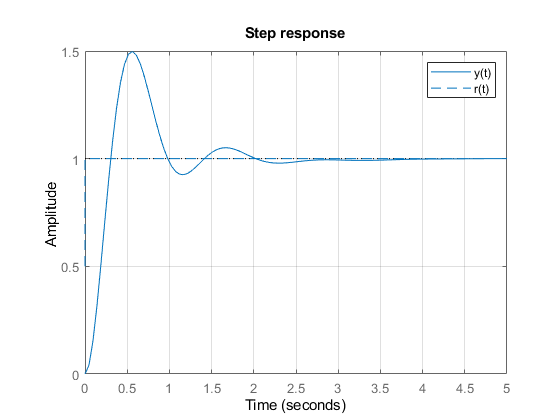

 figure(1)
 step(G0, 5), grid, hold on, title("Step response")
 fplot(heaviside(t),'--'), legend('y(t)', 'r(t)')

 % a regime segue perfettamente l'ingresso quindi l'errore 
 % di posizione è nullo
 
 % errore di velocità
 s = tf('s')

s =
 
  s
 
Continuous-time transfer function.



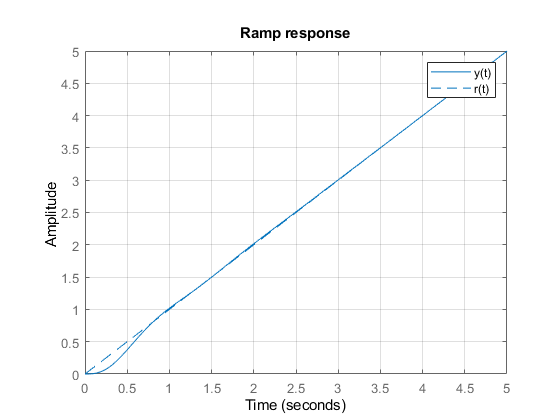

 figure(2)
 step(G0/s, 5), grid, hold on, title("Ramp response")
 fplot(t*heaviside(t),'--'), legend('y(t)', 'r(t)')

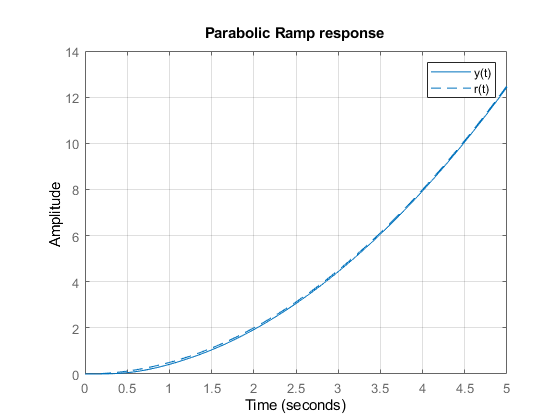

 % errore di velocità è nullo perchè il sis introduce
 % due poli nell'origine 
 
 % errore di accelerazione
 figure(3)
 step(G0/s^2, 5), grid, hold on, title("Parabolic Ramp response")
 fplot(t^2/2*heaviside(t),'--'), legend('y(t)', 'r(t)')

 % errore diverso da 0, molto vicino a 0